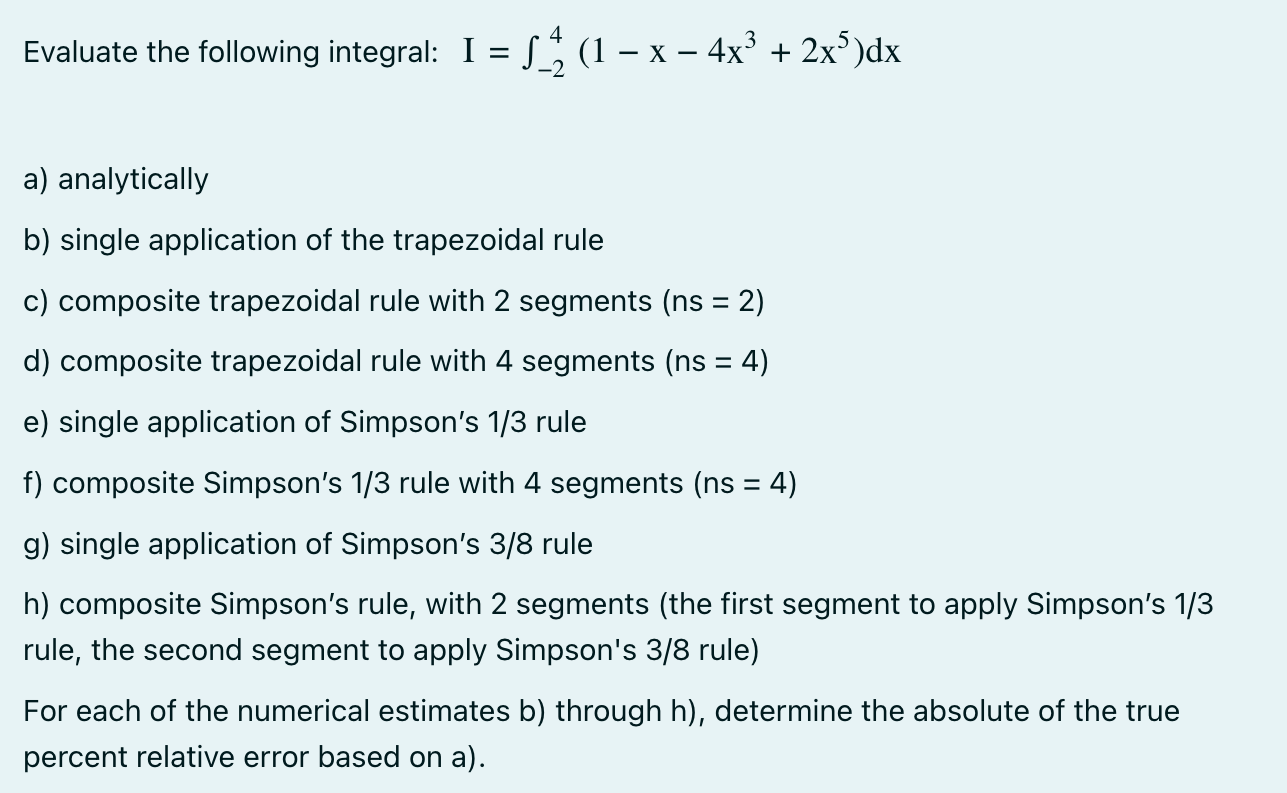

f = @(x) 1 - x - 4 .* x.^3 + 2 .* x.^5;
a = -2;
b = 4;

p = [2 0 -4 0 -1 1];
q = polyint(p);
true = diff(polyval(q, [a b]))

true = 1104

I_trap = trap(f, a, b, 1)

I_trap = 5280

err = abs(((true - I_trap) / true)) * 100

err = 378.2609

I_trap2 = trap(f, a, b, 2)

I_trap2 = 2634

err = abs((true - I_trap2) / true) * 100;
fprintf('%0.4f', err)

138.5870

I_trap4 = trap(f, a, b, 4)

I_trap4 = 1.5169e+03

fprintf('%0.4f', I_trap4)

1516.8750

err = abs((true - I_trap4) / true) * 100;
fprintf('%0.4f', err)

37.3981

ns = 1;
x = linspace(-2,4, 2 * ns + 1);
y = f(x);

h = (b-a)/2;
I_simp13_1 = (h/3) * ((y(1)) + 4*(y(2)) + y(3))

I_simp13_1 = 1752

err = abs(((true - I_simp13_1) / true)) * 100;
fprintf('%0.4f', err)

58.6957

ns = 4;
x = linspace(-2, 4, 2 * ns + 1);
y = f(x);

h = (b - a) / (ns * 2);
for i = 1:ns
    il = 2 * (i - 1) + 1;
    ir = 2 * i + 1;
    simp13_4(i) = (h/3) * ((y(il)) + 4*(y(il + 1)) + y(ir));
end
I_simp13_4 = sum(simp13_4)

I_simp13_4 = 1.1065e+03

fprintf('%0.4f', I_simp13_4)

1106.5312

err = abs(((true - I_simp13_4) / true)) * 100;
fprintf('%0.4f', err)

0.2293

ns = 1;
x = linspace(-2, 4, 3 * ns + 1);
y = f(x);

h = (b-a)/3;
I_simp38_1 = (((3 * h) / 8) * (y(1) + (3 * y(2)) + (3 * y(3)) + y(4)))

I_simp38_1 = 1392

err = abs(((true - I_simp38_1) / true)) * 100;
fprintf('%0.4f', err)

26.0870

ns = 2;
x = linspace(-2, 0, 3);
y = f(x);

h = (0-(-2))/2;
I_simp13 = (h/3) * ((y(1)) + 4*(y(2)) + y(3))

I_simp13 = -4



ns = 3;
x = linspace(0, 4, 4);
y = f(x);
h = (4-0)/3;
I_simp38 = (((3 * h) / 8) * (y(1) + (3 * y(2)) + (3 * y(3)) + y(4)))

I_simp38 = 1.1812e+03


I_combined = I_simp13 + I_simp38

I_combined = 1.1772e+03

fprintf('%0.4f', I_combined)

1177.1852

err = abs((true - I_combined) / true) * 100;
fprintf('%0.4f', err)

6.6291